# opgave 1: sandsynlighedregning

**Vi ønsker at finde tilstedeværelsen af parasitter ved at indsamle afføringsprøver fra råvildt. Den**

**test vi anvender, har sandsynligheden 0,51 for at dyret har parasitten, givet at testen er positiv.**

**Givet at testen er negativ, er der en sandsynlighed på 0,56 for at dyret ikke har parasitten.**

**Sandsynligheden for en positiv test er 0,4.**

*vi stiller vores variabler op*


$$\begin{array}{l}
p=\textrm{dyr}\;\textrm{har}\;\textrm{parsit}\\
\bar{p} =\textrm{dyr}\;\textrm{har}\;\textrm{IKKE}\;\textrm{parsit}\\
t=\textrm{test}\;\textrm{er}\;\textrm{positiv}\\
\bar{t} =\textrm{test}\;\textrm{er}\;\textrm{IKKE}\;\textrm{positiv}
\end{array}$$


ud fra teksten kan vi se at 


$$\begin{array}{l}
\Pr \left(p\left|t\right.\right)=0\ldotp 51\\
\Pr \left(\bar{\;p} \left|\bar{\;t} \right.\right)=0\ldotp 56\\
\Pr \left(t\right)=0\ldotp 4
\end{array}$$


PGivetT=0.51;
invPGivetInvT=0.56;
T=0.4;

og kan regne os frem til disse værdier også 


$$\begin{array}{l}
\Pr \left(\bar{\;p} \left|t\right.\right)=1-\Pr \left(p\left|t\right.\right)\\
\Pr \left(p\left|t\right.\right)=1-\Pr \left(\bar{\;p} \left|\bar{\;t} \right.\right)\\
\Pr \left(\bar{\;t} \right)=1-\Pr \left(t\right)
\end{array}$$


invPGivetT=1-PGivetT;
PGivetInvT=1-invPGivetInvT;
invT=1-T;

**a) Hvad er sandsynligheden for at et dyr både bærer parasitten og testen er positiv.**


$$\Pr \left(p\left|t\right.\right)=\frac{\Pr \left(p\cap t\right)}{\Pr \left(t\right)}\Rightarrow \Pr \left(p\left|t\right.\right)\cdot \Pr \left(t\right)=\Pr \left(p\cap t\right)\;$$


parasitPos_testPos = PGivetT*T

parasitPos_testPos = 0.2040

Der er en sandsynlighed på 0.204 for at dyret både bære parasitten og testen er positiv

**b) Beregn den totale sandsynlighed for at et dyr er bærer af parasitten. Vis også**

**mellemregningerne til hvordan resultatet er fremkommet.**

vi bruger nedenstående formel for total sandsynlighed


$$\Pr \left(p\right)=\Pr \left(p\cap t\right)+\Pr \left(p\cap \bar{t} \right)=\Pr \left(p\cap t\right)+\Pr \left(p\left|\bar{t} \right.\right)*\bar{t}$$


p=parasitPos_testPos+PGivetInvT*invT

p = 0.4680

*Den totale sandsynligheden for at et dyr bære en parasit er 0.4680*

**c) Beregn sandsynligheden for at få en positiv test givet at et dyr er bærer af parasitten. Vis**

**også mellemregningerne til hvordan resultatet er fremkommet.**


$$\Pr \left(t\left|p\right.\right)=\frac{\Pr \left(t\cap p\right)}{\Pr \left(p\right)}=\frac{\;\Pr \left(p\left|t\right.\right)\cdot \Pr \left(t\right)}{\Pr \left(p\right)}$$


TGivetP= (PGivetT*T)/p

TGivetP = 0.4359

*Sandsynligheden for at få en positiv test givet at dyret bærer en parasit er 0.436*

# Opgave2: stokastiske variable

En kontinuert stokastisk variabel X, har en cdf Fx(x) givet som:

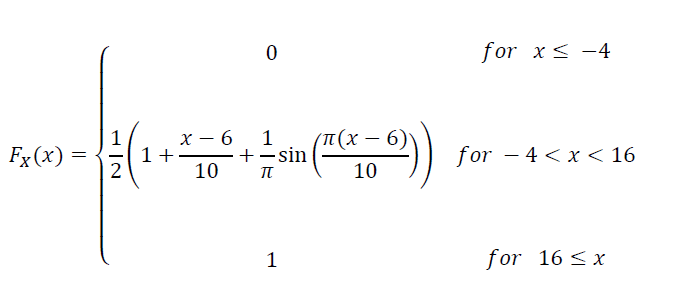

**a) Hvad er sandsynligheden for Pr(X>5) (dvs. at den stokastiske variabel X antager en værdi, der**

**er større end 5.**

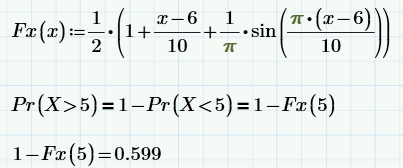

vi indsætter formlen for Fx(x) og ud fra formlen kan vi se at for at finde Pr(X>5) skal vi trække 1 fra Fx(5)

vi ender med en sandsynlighed på 0.599.

*Sandsynligheden for Pr(X>5) er 0.599*

**b) Hvad er sandsynligheden for Pr(X=5)?**

**for at finde sandsynligheden indsættes 5 ind på x's plads i **$F_X \left(x\right)$


$$F_X \left(5\right)=\frac{1}{2}\cdot \left(1+\frac{\;5-6}{10}+\frac{\;1}{\pi \;}\cdot \sin \;\left(\frac{\;\pi \;\left(5-6\right)}{10}\right)\right)$$


FX5=(1/2)*(1+((5-6)/10)+(1/pi)*sin((pi*(5-6))/10))

FX5 = 0.4008

Dette kan også bekræftes med samme udregning i mathcad

*Sandsynligheden for at Pr(X=5) er 0.4008*

**c) Bestem og skitsér pdf’en  **$f_X \left(x\right)$** for X i intervallet -4 til 16.**

i det at cdf er integralet af en pdf skal vi differentiere cdf'en for at finde pdf'en

efter differentiering får vi funktionen:


$$f\left(x\right)=\frac{\;\cos \left(\frac{\;\pi \cdot \left(x-6\right)}{10}\right)}{20}+\frac{1}{20}$$


kan bekræftes med mathcad

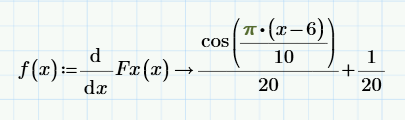

f(x) kan plottes ind og vi får:

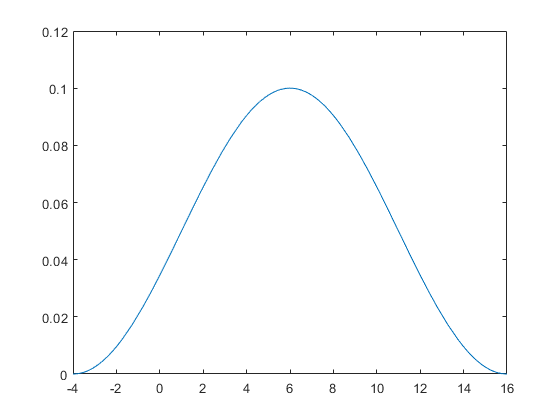

syms x;
f(x)=((cos((pi*(x-6))/(10)))/(20))+(1/20);
figure(1)
fplot(f(x))
axis([-4,16,0,0.12])

Kan også bekræftes med mathcad

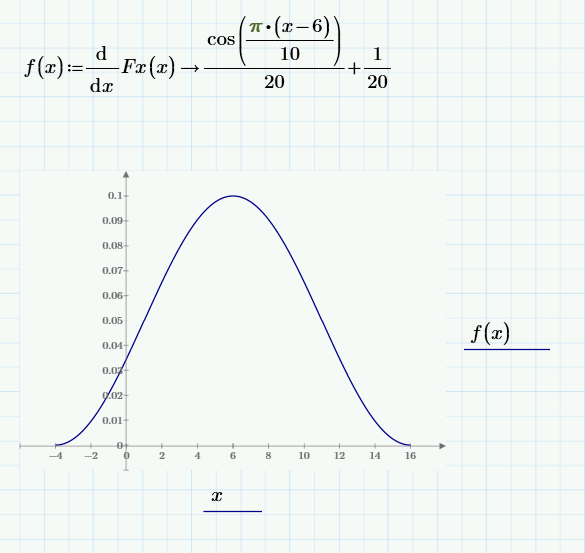

**d) Opstil udtrykket for og find middelværdien for X.**

**I det at det er en kontinueret funktion der arbejdes med bruges nedenstående formel for udregning af middelværdien**


$$E\left\lbrack X\right\rbrack =\textrm{EX}=\mu =\int_{-\infty \;}^{\infty \;} x\cdot f_x \left(x\right)\textrm{dx}$$


I vores tilfælde giver det ikke mening at gå fra negativ uendelig til uendelig vi går derfor fra -4 til 16

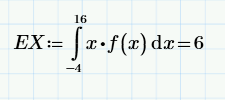

vi får derved en middelværdi for x på 6

*EX=6*

**e) Opstil udtrykket for og find variansen for X.**

**for at finde variansen ved vi at vi kan sige **


$$\textrm{var}\left(x\right)=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


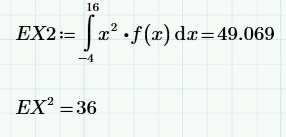

regnestykket lyder derfor således:


$$\begin{array}{l}
\textrm{var}\left(x\right)=49\ldotp 069-36\\
\textrm{var}\left(x\right)=13\ldotp 069
\end{array}$$


som også kan bekræftes i mathcad

*Var(x)=13.069*

# Opgave 3: Stokastiske Processer

**En diskret stokastisk proces X[n]er givet ved:**


$$X\left\lbrack n\right\rbrack =-Y+W\left\lbrack n\right\rbrack$$


**Hvor Y er binomial fordelt og W[n] er normalfordelt:**


$$Y~B\left(n=2,p=0\ldotp 2\right)\;\;W\left\lbrack n\right\rbrack ~N\left(0,2\right)$$


**Desuden er Y og W[n] uafhængige.**

**a) Skitsér 1 realisation med 11 samples (n=0, …,10) af en realisation af den stokastiske proces X[n]. Angiv hvordan processen er simuleret (brug f.eks. binornd() og randn() e.l. i Matlab).**

%One realization 11 samples
Wsigma = 2;
Wmu = 0;
Wn=randn(1,11)*sqrt(Wsigma);

Yn=2;
Yp=0.2;
Y=binornd(Yn,Yp);

Xn=-Y+Wn

Xn =    -1.6222   -1.5116   -1.1448   -4.1638    2.0342    0.4599   -1.0676    1.9379   -2.4204   -0.1446   -0.3415


    TidsligMiddel = sum(Xn)/11

TidsligMiddel = -0.7259

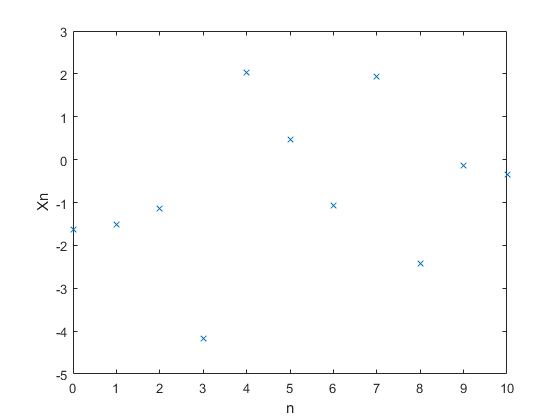

    figure(2)
    plot(0:10,Xn,'x')
    xlabel('n')
    ylabel('Xn')

*Processen er simuleret ved brug af matlabs binomial random funktion samt normale random funktion,*

* som ud fra input kan generer noget passende tilfældigt data.*

*Efter at have simuleret de 2 stokastiske variabler, kan de bruges til at udregne Xn samt simulere den.*

**b) Opstil formlerne for og bestem ensemble-middelværdien og -variansen for den stokastiske proces X[n].**

ensamble middelværdien udregnes udfra nedenstående formel


$${\textrm{EX}}_n =-\left(n\cdot p\right)+0\Rightarrow {\textrm{EX}}_n =-\left(2\cdot \;0\ldotp 2\right)+0=-0\ldotp 4$$
 

middelværdien for en binormialfordeling er $n\cdot \;p$

middelværdien for en normalfordeling er $\mu \;$

varians for binormialfordeling udregnes ved at sige $n\cdot \;p\left(1-p\right)$

varians for normalfordeling udregnes ved at sige $\sigma {\;}^2$


$$\textrm{Var}\left(x\right)=-\left(n\cdot \;p\left(1-p\right)\right)+\sigma {\;}^2 \Rightarrow -\left(2\cdot 0\ldotp 2\left(1-0\ldotp 2\right)\right)+2=1\ldotp 68$$


although it's in reality this...

*Vi ender med en middel på -0.4 og en varians på 2.32*

***SOMETHING IS ROTTEN: Why is the minus written as (-1)^2 in the solution which gives us +1***

**c) Opstil formlen for den tidslige middelværdi (gennemsnitværdien) for én realisation.**

**Den tidslige middel blev fundet i opgave 3a men er vidst forneden.**

**Den brugte formel er **$\frac{\sum_{i=1}^{11} X\left\lbrack n_i \right\rbrack }{11}$

    TidsligMiddel

TidsligMiddel = -0.7259

**d) Angiv om den stokastiske proces er stationær i den brede forstand/Wide Sense Stationary (WSS), og om den er ergodisk. Svarene skal begrundes.**

Da tid ikke er en faktor i processen er den stokastiske process WSS, det bunder at E[X] og var(x) er uafhængige af tid. Den er ikke ergodisk da den udregnede ensemble middel ikke er det samme som den tidslige middel.

Den stokastiske process er WSS 

Den stokastiske process er IKKE ergodisk

# Opgave 4: Statisktik

**En artikel påstår, at antallet at cigaretter solgt om året pr. indbygger i Danmark mellem 1955-1970 var lineært stigende.**

** Dette ønsker vi nu at eftervise. Antallet af cigaretter er givet ved ”Antal” i tabellen, og årstallet er givet ved ”År”:**

**a) Plot data fra tabellen. Overvej hvilke værdier, der skal ud ad x-aksen og hvilke, der skal plottes ud ad y-aksen.**

**Tommelfinger reglen siger at tid altid skal være på x-aksen**

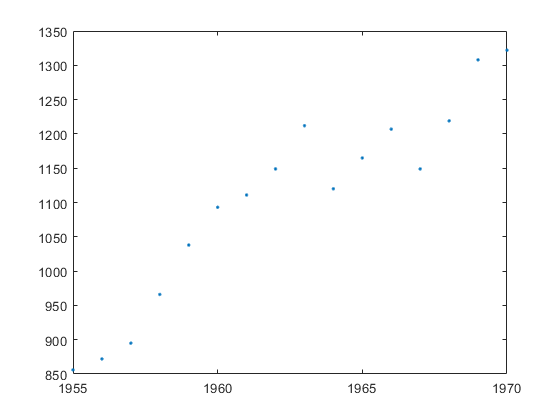

    year = [1955 1956 1957 1958 1959 1960 1961 1962 1963 1964 1965 1966 1967 1968 1969 1970];
    num = [856 872 895 966 1038 1093 1111 1149 1212 1120 1165 1207 1149 1219 1308 1322];
    figure(3)
    plot(year,num,'.')

**b) Find gennemsnittet af År og Antal.**


$$\mu {\;}_y =\frac{\sum_{i=1}^{16} {\textrm{year}}_i }{16}$$



$$\mu {\;}_n =\frac{\sum_{i=1}^{16} {\textrm{num}}_i }{16}$$


    mu_n=sum(num)/length(num)

mu_n = 1.1051e+03

    mu_y=sum(year)/length(year)

mu_y = 1.9625e+03

*gennemsnit for år er 1962.5*

*gennemsnit for antal er 1105.5*

**c) Beregn skæringen og hældningen for den lineære regression. Angiv desuden formlerne, der er brugt ved beregningen. Indtegn den rette linje på plottet.**


$$\beta =\frac{\sum_{i=1}^{16} \left(y_i -\mu {\;}_y \right)\cdot \left(n_i -\mu {\;}_{n\;} \right)}{\sum_{i=1}^{16} {\left(y_i -\mu {\;}_y \right)}^2 }$$



$$\alpha =\mu {\;}_n -\beta \cdot \mu {\;}_y$$


beta_taeller= 0;
beta_naevner= 0;
for n=1:length(year)%der er samme mængde data for begge arrays så det gør ikke nogen forskel hvilken der bruges
    beta_taeller = beta_taeller + (year(n)-mu_y)*(num(n)-mu_n);
    beta_naevner = beta_naevner + (year(n)-mu_y).^2;% every element is taken to the power of 2
end
beta = beta_taeller/beta_naevner%Dette er hældningen

beta = 28.6794

alpha = mu_n-beta*mu_y%dette er skæringen

alpha = -5.5178e+04

Dette betyder at vi har en signal model der lyder således


$$N=-55178\ldotp 22+28\ldotp 68\cdot Y+\varepsilon$$


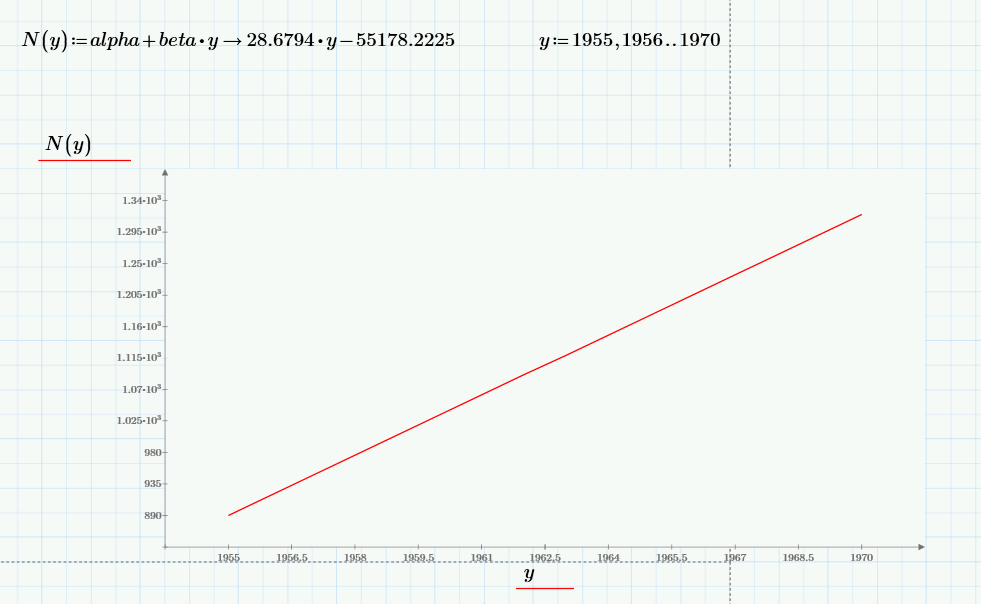

*Den linæere regressions linje, dog uden datapunkterne*

**d) Lav et residual-plot på en graf. Angiv desuden hvordan residualerne i plottene beregnes (dvs. angiv formlerne, der er brugt ved beregningen).**

Tager vi den originale formel 


$$N=\alpha +\beta \cdot Y+\varepsilon$$


kan vi isolere epsilon, og ender derfor med 


$$\varepsilon {\;}_i =N_i -\alpha +\beta \cdot Y_i$$


Vi indsætter de respektive værdier fra de to data lister ind og finder risidualet for det specifikke datapunkt 

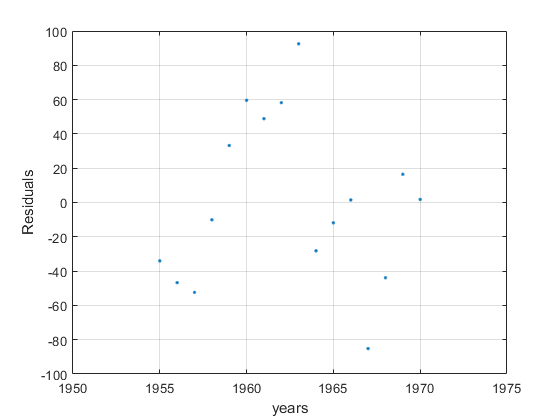

epsilon = num-(alpha+(beta*year));
figure(5)
plot(year,epsilon,'.')
axis([1950 1975 -100 100])
xlabel('years')
ylabel('Residuals')

grid on

**e) Opstil en hypotesetest på om hældningen er 0.**

 H0: $\beta \;=0$, Hældning er 0

 H1: $\beta \not= 0$, hældning er ikke 0

**f) Beregn t-værdien og p-værdien for hypotesen.**


$$S_r^2 =\frac{1}{n-2}\cdot \;\sum_{i=1}^n {\left(y_i -\left(\alpha +\beta \cdot x_i \right)\right)}^2$$


sr2=(1)/(length(year)-2)*sum((num-(alpha+beta*year)).^2);


$$S_{\textrm{xx}} =\;\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2$$


sxx=sum((year-mu_y).^2);

Hnull_beta0=0;


$$t=\frac{\beta -\beta {\;}_{0\;} }{\sqrt{\frac{S_r^2 }{S_{\textrm{xx}} }}}$$


t=(beta- Hnull_beta0)/(sqrt(sr2/sxx))

t = 10.4912


$$\textrm{pval}=2\cdot \;\left(1-t_{\textrm{cdf}} \left(\left|t\right|,n-2\right)\right)$$


p=2*(1-tcdf(abs(t),length(year)-2))

p = 5.1411e-08

*Vi ender med en t-værdi på 10.49 og en p-værdi på *$5\ldotp 14\cdot {10}^{-8\;}$

I det at p-værdien er meget under 0.05 betyder det at vi kan afvise nulhypotesen.

H0 er afvist, som betyder at $\beta {\;}_0 \not= 0$

**g) Kan det afvises at hældningen på den lineære regression er 0 med en konfidensniveau på 95%?**

vi bruger formlen 


$$t_0 =\textrm{tinv}\left(1-\frac{0\ldotp 05}{2},n-2\right)=\textrm{tinv}\left(0\ldotp 975,n-2\right)$$


t0=tinv(0.975,length(year)-2)

t0 = 2.1448

herefter kan den nedre og øvre grænse findes


$${\beta \;}_- =\beta -t_0 \cdot \sqrt{\frac{S_r^2 }{S_{\textrm{xx}} }}$$


Beta_nedre=beta-t0*sqrt(sr2/sxx)

Beta_nedre = 22.8163


$${\beta \;}_+ =\beta +t_0 \cdot \sqrt{\frac{S_r^2 }{S_{\textrm{xx}} }}$$


Beta_oevre=beta+t0*sqrt(sr2/sxx)

Beta_oevre = 34.5425

Konfidens intervalelt fortæller os at betas nedre værdi er større end nullhypotesen.

Dette betyder at vi kan afvise nullhypotesen og bekræfte at hældningen **ikke** er ligmed 0 med et konfidensniveau på 95%.